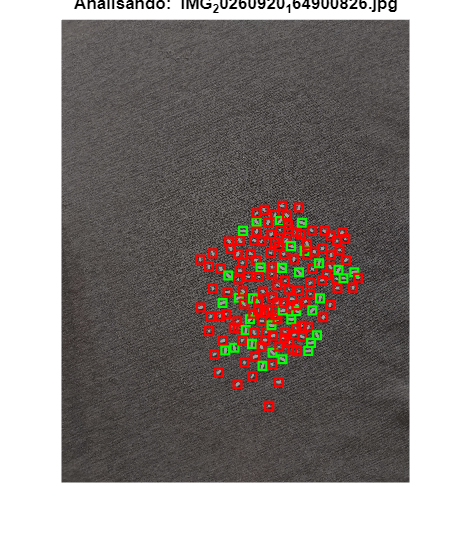

Imagem IMG_20260911_154655656.jpg: Tipo1: 46 | Tipo 3/4: 4
Imagem IMG_20260911_160514406.jpg: Tipo1: 27 | Tipo 3/4: 23
Imagem IMG_20260911_170612628.jpg: Tipo1: 59 | Tipo 3/4: 31
Imagem IMG_20260911_171304388.jpg: Tipo1: 92 | Tipo 3/4: 41
Imagem IMG_20260911_171807132.jpg: Tipo1: 67 | Tipo 3/4: 77
Imagem IMG_20260911_172306603.jpg: Tipo1: 78 | Tipo 3/4: 62
Imagem IMG_20260911_172842094.jpg: Tipo1: 57 | Tipo 3/4: 80
Imagem IMG_20260913_154100524.jpg: Tipo1: 22 | Tipo 3/4: 41
Imagem IMG_20260913_154718887.jpg: Tipo1: 33 | Tipo 3/4: 194
Imagem IMG_20260913_155132563.jpg: Tipo1: 34 | Tipo 3/4: 114
Imagem IMG_20260913_155714564.jpg: Tipo1: 60 | Tipo 3/4: 120
Imagem IMG_20260913_160348512.jpg: Tipo1: 53 | Tipo 3/4: 304
Imagem IMG_20260913_160906417.jpg: Tipo1: 31 | Tipo 3/4: 225
Imagem IMG_20260913_162414751.jpg: Tipo1: 65 | Tipo 3/4: 198
Imagem IMG_20260913_163945095.jpg: Tipo1: 65 | Tipo 3/4: 380
Imagem IMG_20260913_182536636.jpg: Tipo1: 38 | Tipo 3/4: 105
Imagem IMG_20260913_194140081.jpg

Imagem IMG_20260920_164900826.jpg: Tipo1: 34 | Tipo 3/4: 123


%% --- 1. Configurações Iniciais e Pastas ---
clear; clc; close all;

VISUALIZAR = true;   
pasta_origem = 'fotos_coletadas'; 
outputRoot = 'dataset_qualidade_gray';

classTipo1 = fullfile(outputRoot, 'arroz_tipo1');     
classTipo34 = fullfile(outputRoot, 'arroz_tipo3_4');  

if ~exist(classTipo1, 'dir'), mkdir(classTipo1); end
if ~exist(classTipo34, 'dir'), mkdir(classTipo34); end

arquivos = dir(fullfile(pasta_origem, '*.jpg'));
if isempty(arquivos), error('Pasta vazia!'); end

% Configurações do Algoritmo
cropSize = 70;
targetSize = [20 20]; 
threshold_comprimento = 55; 

total_tipo1 = 0;
total_tipo34 = 0;

if VISUALIZAR
    hFig = figure('Name', 'Classificação de Qualidade - Tipo 1 vs Tipo 3/4', ...
           'NumberTitle', 'off', 'WindowState', 'maximized');
end

%% --- 2. Loop Principal ---
for k = 1:length(arquivos)
    nomeArquivo = arquivos(k).name;
    caminhoCompleto = fullfile(arquivos(k).folder, nomeArquivo);
    [~, nomeBase, ~] = fileparts(nomeArquivo);
    
    try
        img = imread(caminhoCompleto);
        imgDouble = im2double(img);
        
        % --- 3. Segmentação ---
        R = imgDouble(:,:,1); G = imgDouble(:,:,2); B = imgDouble(:,:,3);
        I = (R + G + B) / 3;
        S = max(max(abs(R - G), abs(R - B)), abs(G - B));
        mask = ((I > 0.75) & (S < 0.15)) | ((I > 0.45) & (I <= 0.75) & (S < 0.10));
        mask = bwareaopen(imfill(mask, 'holes'), 40);
        mask = imopen(imclose(mask, strel('disk', 2)), strel('disk', 1));

        % --- Visualização da máscara binária ---
        % figure('Name', 'Máscara Binária', ...
        %        'NumberTitle', 'off', ...
        %        'WindowState', 'maximized');
        % 
        % imshow(mask);
        % title(sprintf('Máscara binária - %s', nomeArquivo), ...
        %       'Interpreter', 'none');

        CC = bwconncomp(mask);
        stats = regionprops(CC, 'Centroid', 'Area', 'MajorAxisLength', 'Orientation');
        
        valid_idx = find([stats.Area] > 200 & [stats.Area] < 2000);
        
        if VISUALIZAR
            figure(hFig); clf; imshow(img); hold on;
            title(sprintf('Analisando: %s', nomeArquivo));
        end

        count_t1_local = 0;
        count_t34_local = 0;
        
        for i = 1:length(valid_idx)
            idx = valid_idx(i);
            centro = stats(idx).Centroid;
            comprimento = stats(idx).MajorAxisLength;
            
            % --- LÓGICA DE CLASSIFICAÇÃO ---
            if comprimento >= threshold_comprimento
                pastaDestino = classTipo1;
                tipo = 'tipo1';
                corBox = 'g'; % Verde para Inteiro
                count_t1_local = count_t1_local + 1;
            else
                pastaDestino = classTipo34;
                tipo = 'tipo34';
                corBox = 'r'; % Vermelho para Quebrado
                count_t34_local = count_t34_local + 1;
            end
            
            % Recorte e Processamento
            x1 = round(centro(1) - cropSize/2);
            y1 = round(centro(2) - cropSize/2);
            rect = [max(1,x1), max(1,y1), cropSize-1, cropSize-1];
            
            if (rect(1)+rect(3) <= size(img,2)) && (rect(2)+rect(4) <= size(img,1))
                
                % Visualização
                if VISUALIZAR
                    rectangle('Position', rect, 'EdgeColor', corBox, 'LineWidth', 1.5);
                end

                % Preparação para o Dataset (Cinza 20x20)
                recorteRGB = imcrop(img, rect);
                recorteGray = rgb2gray(recorteRGB);
                recorteFinal = imresize(recorteGray, targetSize);
                
                % Salva
                nomeFinal = sprintf('%s_%s_%03d.png', nomeBase, tipo, i);
                imwrite(recorteFinal, fullfile(pastaDestino, nomeFinal));
            end
        end
        
        fprintf('Imagem %s: Tipo1: %d | Tipo 3/4: %d\n', nomeArquivo, count_t1_local, count_t34_local);
        
        total_tipo1 = total_tipo1 + count_t1_local;
        total_tipo34 = total_tipo34 + count_t34_local;

    catch ME
        fprintf('Erro na imagem %s: %s\n', nomeArquivo, ME.message);
    end
end


fprintf('\n=== RESUMO FINAL ===\n');


=== RESUMO FINAL ===


fprintf('Total Tipo 1 (Inteiros): %d\n', total_tipo1);

Total Tipo 1 (Inteiros): 5084


fprintf('Total Tipo 3/4 (Quebrados): %d\n', total_tipo34);

Total Tipo 3/4 (Quebrados): 5067
